# Examples of use

## Solving nonlinear equations with general methods

### Newton's method (includes Scaling Theorem)


$$p(z)=(z-a)(z-b)$$


% Rational operator
syms z a b
p=(z-a)*(z-b);
dp=diff(p,z);
N=simplify(z-p/dp);
h=(z-a)/(z-b);
h1=(b*z-a)/(z-1);
NM=simplify(subs(h,z,subs(N,z,h1)))

$$NM = z^{2}$$

NM=matlabFunction(NM);

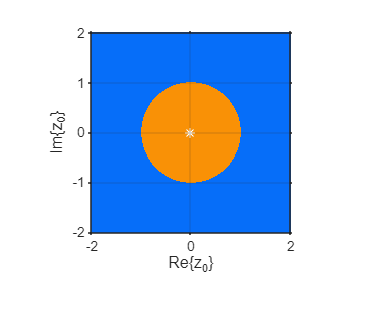

% Generation of the dynamical plane
N=200; tol=1e-6; limits=[-2 2 -2 2]; roots=0;
ZN24=dynPlane(NM,N,tol,limits,roots);
% Representation of the dynamical plane
plotDynPlane(ZN24,tol,limits,roots)
plot(real(roots),imag(roots),'w*')

### Steffensen's method 

$p(z)=(z-a)(z-b)$, for $a=-1$, $b=3$.

% Rational operator
syms z
a=-1; b=3;
p=(z-a)*(z-b);
w=z+p;
pw=subs(p,z,w);
S=simplify(z-p^2/(pw-p));
S=matlabFunction(S);

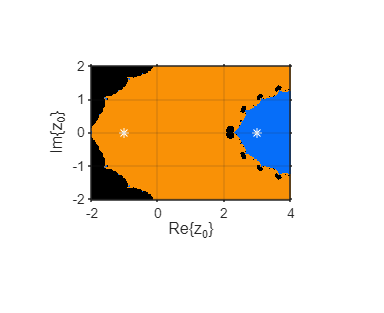

% Generation of the dynamical plane
N=200; tol=1e-6; limits=[-2 4 -2 2]; roots=[-1 3];
ZS24=dynPlane(S,N,tol,limits,roots);
% Representation of the dynamical plane
plotDynPlane(ZS24,tol,limits,roots)
plot(real(roots),imag(roots),'w*')

## Solving nonlinear equations with methods with memory

### Secant method

$p(x)=(x-a)(x-b)$ for $a=2$, $b=-\frac{1}{2}$.

% Rational operator
syms x0 x1 
a=2; b=-1/2;
p0=(x0-a)*(x0-b);
p1=(x1-a)*(x1-b);
SEC=simplify(x1-p1*(x1-x0)/(p1-p0));
SEC=matlabFunction(SEC);
SEC=func2str(SEC);
SEC=replace(SEC,'x0,x1','x');
SEC=replace(SEC,'x0','x(:,1)');
SEC=replace(SEC,'x1','x(:,2)');
SEC=str2func(SEC);

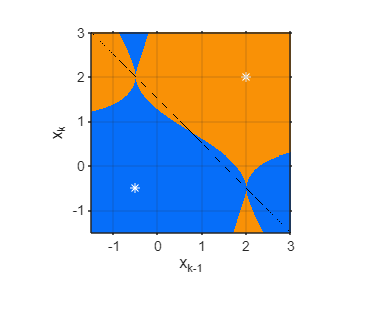

% Generation of the dynamical plane
N=200; tol=1e-6; limits=[-3/2 3 -3/2 3]; roots=[2 -1/2];
ZSEC24=dynPlaneMemo(SEC,N,tol,limits,roots);
% Representation of the dynamical plane
plotDynPlane(ZSEC24,tol,limits,roots)
plot(roots,roots,'w*')
xlabel('x_{k-1}'), ylabel('x_{k}')

## Solving nonlinear systems of equations with general methods

### Newton's method

$p(\bar{x})=\bar{x}^2-1$, where $\bar{x}=(x_1, x_2)^T$

% Rational operator
syms x [2 1]
F=x.^2-1;
dF=jacobian(F);
SN=matlabFunction(x-dF\F);

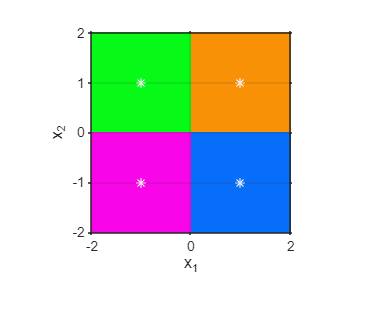

% Generation of the dynamical plane
N=200; tol=1e-6; limits=[-2 2 -2 2]; roots=[1 1 -1 -1;1 -1 1 -1];
ZNS24=dynPlaneSystem(SN,N,tol,limits,roots);
% Representation of the dynamical plane
plotDynPlane(ZNS24,tol,limits,roots)
plot(roots(1,:),roots(2,:),'w*')
xlabel('x_1'), ylabel('x_2')